**Exercise 1**

A heat sink has 30x50 mm 2D fins. Find the steady-state temperature distribution in the fins using the Direct Method.


$$\frac{\partial^2 T}{\partial x^2 }+\frac{\partial^2 T}{\partial y^2 }=0$$


Suppose the hot component at $90^{\circ}C$and all other edges of the fins at room temperature ($25^{\circ}C$).

The problem is handled with only Dirichlet boundary conditions. Use $\Delta x = \Delta y = 1 mm$.

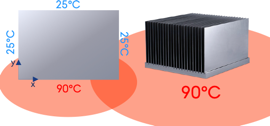

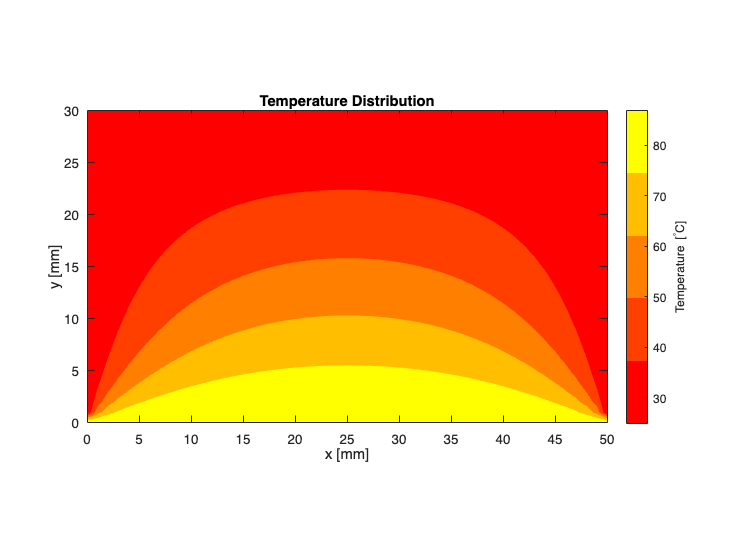

%% Laplace Equation Exercise 1
% Direct method for 2D steady-state heat conduction
clc; clear variables; close all;

% geometry/mesh definition
Lx = 50;              % mm
Ly = 30;              % mm
dx = 1;               % mm
dy = 1;               % mm

N = Lx/dx + 1;        % number of nodes in x-direction
M = Ly/dy + 1;        % number of nodes in y-direction

x = linspace(0,Lx,N);
y = linspace(0,Ly,M);

Asz = N*M;            % total number of unknowns

% boundary temperatures
T_hot  = 90;          % bottom edge
T_room = 25;          % top, left, right edges

%% Build linear system A*u = b
A = sparse(Asz,Asz);
b = zeros(Asz,1);

% node numbering:
% k = (j-1)*N + i
% i = 1...N  (x-direction)
% j = 1...M  (y-direction)

for j = 1:M
    for i = 1:N
        k = (j-1)*N + i;

        % --- Dirichlet boundary nodes ---
        if j == 1                      % bottom boundary: 90 C
            A(k,k) = 1;
            b(k) = T_hot;

        elseif j == M                  % top boundary: 25 C
            A(k,k) = 1;
            b(k) = T_room;

        elseif i == 1                  % left boundary: 25 C
            A(k,k) = 1;
            b(k) = T_room;

        elseif i == N                  % right boundary: 25 C
            A(k,k) = 1;
            b(k) = T_room;

        % --- Interior nodes ---
        else
            k_left  = k - 1;
            k_right = k + 1;
            k_down  = k - N;
            k_up    = k + N;

            A(k,k)       = -4;
            A(k,k_left)  = 1;
            A(k,k_right) = 1;
            A(k,k_down)  = 1;
            A(k,k_up)    = 1;
            b(k) = 0;
        end
    end
end

%% Solve directly
u_vec = A\b;

% reshape solution vector into matrix u(i,j)
u = reshape(u_vec, [N,M]);

%% plot solution
figure
[X,Y] = meshgrid(x,y);
contourf(X,Y,u',20,'LineColor','none');
hc = colorbar;
ylabel(hc,'Temperature [^\circC]')
colormap autumn(5)
title('Temperature Distribution')
axis equal
xlabel('x [mm]')
ylabel('y [mm]')
xlim([0 Lx])
ylim([0 Ly])

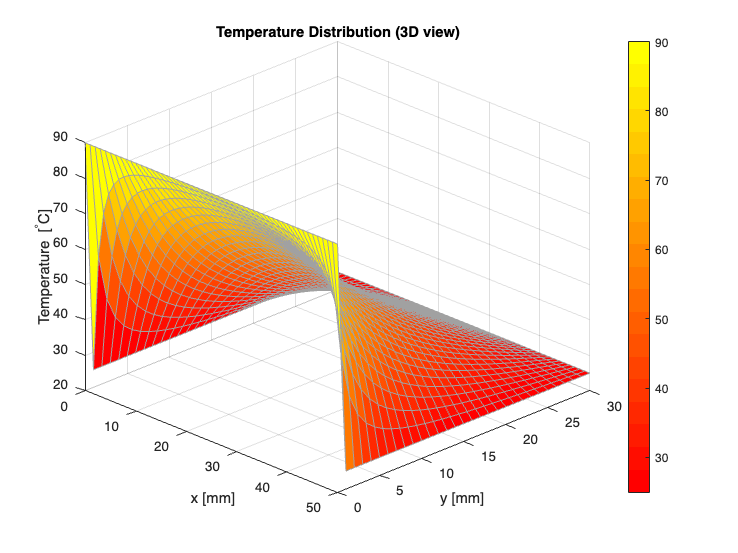


figure
surf(X,Y,u','EdgeColor','#a1a1a1')
colorbar
colormap autumn(20)
title('Temperature Distribution (3D view)')
xlabel('x [mm]')
ylabel('y [mm]')
zlabel('Temperature [^\circC]')
view(45,30)

**Exercise 2**

Try to solve the EXERCISE 1 by iterative methods:

- Jacobi Method

- Gauss-Seidel Method

Iterate until no $T_{i,j}$ changes more than 0.01 per iteration.

Note: assign zero to all grid points as initial guess.

Compare the number of iterations in the two methods for achieving the requested accuracy.

%% Laplace Equation Exercise 2
% Jacobi and Gauss-Seidel methods
clc; clear variables; close all;

%% geometry/mesh definition
Lx = 50;          % mm
Ly = 30;          % mm
dx = 1;           % mm
dy = 1;           % mm

N = Lx/dx + 1;    % number of nodes in x
M = Ly/dy + 1;    % number of nodes in y

x = linspace(0,Lx,N);
y = linspace(0,Ly,M);

% boundary temperatures
T_hot  = 90;      % bottom edge
T_room = 25;      % top, left, right edges

tol = 0.01;       % stopping criterion
maxIter = 100000; % Iteration limit

% Jacobi
u_old = zeros(N,M);
u_new = zeros(N,M);

% impose boundary conditions
u_old(:,1) = T_hot;      % bottom
u_old(:,M) = T_room;     % top
u_old(1,:) = T_room;     % left
u_old(N,:) = T_room;     % right

u_new = u_old;

iterJ = 0;
errJ = inf;

while errJ > tol && iterJ < maxIter
    iterJ = iterJ + 1;

    % update only interior nodes using OLD values
    for i = 2:N-1
        for j = 2:M-1
            u_new(i,j) = 0.25 * (u_old(i+1,j) + u_old(i-1,j) + u_old(i,j+1) + u_old(i,j-1));
        end
    end

    % compute max change
    errJ = max(max(abs(u_new - u_old)));

    % prepare next iteration
    u_old = u_new;
end

u_jacobi = u_new;

% Gauss-Seidel
u_gs = zeros(N,M);

% boundary conditions
u_gs(:,1) = T_hot;       % bottom
u_gs(:,M) = T_room;      % top
u_gs(1,:) = T_room;      % left
u_gs(N,:) = T_room;      % right

iterGS = 0;
errGS = inf;

while errGS > tol && iterGS < maxIter
    iterGS = iterGS + 1;
    errGS = 0;

    % update in-place using newest available values
    for i = 2:N-1
        for j = 2:M-1
            old_val = u_gs(i,j);

            u_gs(i,j) = 0.25 * (u_gs(i+1,j) + u_gs(i-1,j) + u_gs(i,j+1) + u_gs(i,j-1));

            change = abs(u_gs(i,j) - old_val);
            if change > errGS
                errGS = change;
            end
        end
    end
end

%% results
fprintf('Jacobi method:\n');

Jacobi method:


fprintf('  Iterations = %d\n', iterJ);

  Iterations = 908


fprintf('  Final max change = %.6f\n\n', errJ);

  Final max change = 0.009974




fprintf('Gauss-Seidel method:\n');

Gauss-Seidel method:


fprintf('  Iterations = %d\n', iterGS);

  Iterations = 545


fprintf('  Final max change = %.6f\n\n', errGS);

  Final max change = 0.009939




if iterGS < iterJ
    fprintf('Gauss-Seidel converged faster by %d iterations.\n', iterJ - iterGS);
elseif iterJ < iterGS
    fprintf('Jacobi converged faster by %d iterations.\n', iterGS - iterJ);
else
    fprintf('Both methods used the same number of iterations.\n');
end

Gauss-Seidel converged faster by 363 iterations.


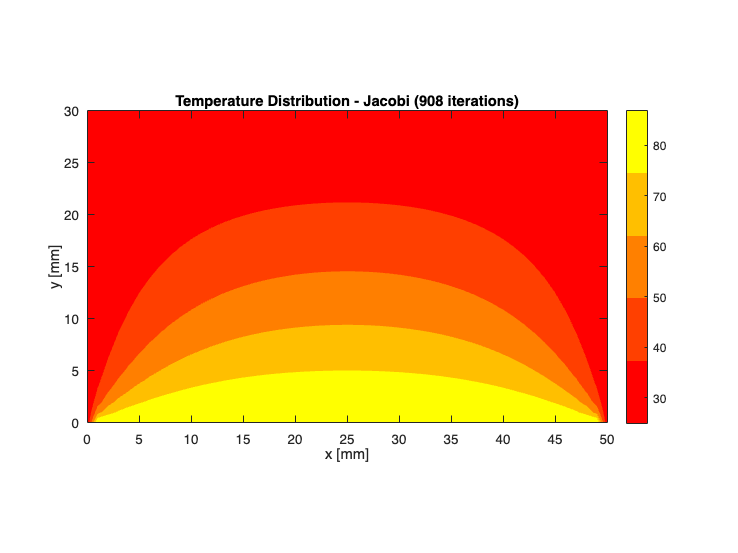


%% plot Jacobi
figure
[X,Y] = meshgrid(x,y);
contourf(X,Y,u_jacobi',20,'LineColor','none')
colorbar
colormap autumn(5)
title(sprintf('Temperature Distribution - Jacobi (%d iterations)',iterJ))
axis equal
xlabel('x [mm]')
ylabel('y [mm]')
xlim([0 Lx])
ylim([0 Ly])

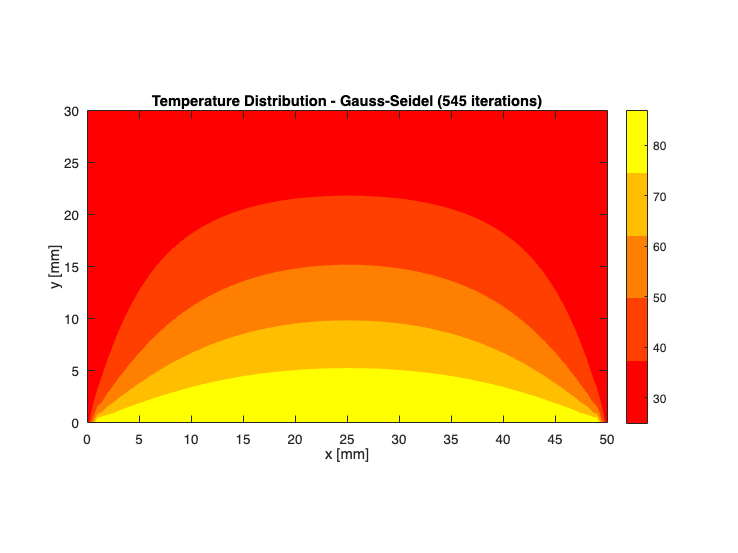


%% plot Gauss-Seidel
figure
contourf(X,Y,u_gs',20,'LineColor','none')
colorbar
colormap autumn(5)
title(sprintf('Temperature Distribution - Gauss-Seidel (%d iterations)',iterGS))
axis equal
xlabel('x [mm]')
ylabel('y [mm]')
xlim([0 Lx])
ylim([0 Ly])